## AAE334L L3 MATLAB CODE AUTHOR: TOMOKI KOIKE

close all; clear all; clc;
set(groot, 'defaulttextinterpreter',"latex");
set(groot, 'defaultAxesTickLabelInterpreter',"latex");
set(groot, 'defaultLegendInterpreter',"latex");

### Calibration 

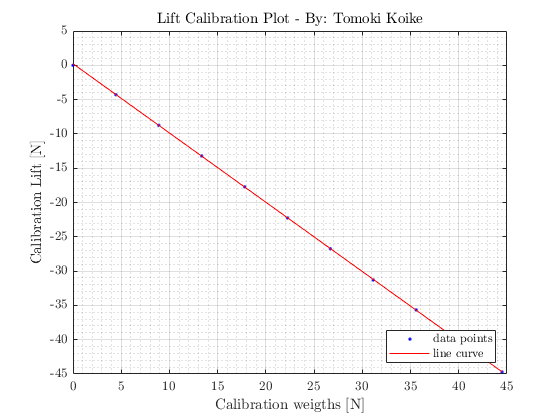

% Importing the calibration data file as a matrix 
calib_data = rmmissing(readmatrix("calibration.xlsx"));
calib_data = [calib_data(1:11,:); calib_data(1,:); calib_data(11+1:end,:)];

calib_weights = lbs2newton(calib_data(1:11,1));  % the calibration weights [lbs]
calib_lifts = lbs2newton(calib_data(1:11,7));  % the calibrated lift [lbf]
calib_drags = lbs2newton(calib_data(12:end,6));  % the calibrated drag [lbf]
% calib_vel_L = calib_data(1:11,4);  % calibartion velocity for lift [m/s]
% calib_vel_D = calib_data(12:end,4);  % calibration velocity for drag [m/s]
% calib_pf_L = calib_data(1:11,2);  % calibration reference pressure for lift
% calib_pf_D = calib_data(12:end,2);  % calibration reference pressure for drag
% calib_rho_L = calc_density(calib_pf_L);  % calibration density for lift [kg/m^3]
% calib_rho_D = calc_density(calib_pf_D);  % calibration density for drag [kg/m^3]

% Fitting calibration data
% lift
[res_lift gof_lift] = createFit(calib_weights, calib_lifts, 'Lift');

disp(res_lift);

     Linear model Poly2:
     res_lift(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =   6.763e-06  (-0.0002099, 0.0002234)
       p2 =       -1.01  (-1.02, -0.9999)
       p3 =      0.2284  (0.1328, 0.3241)


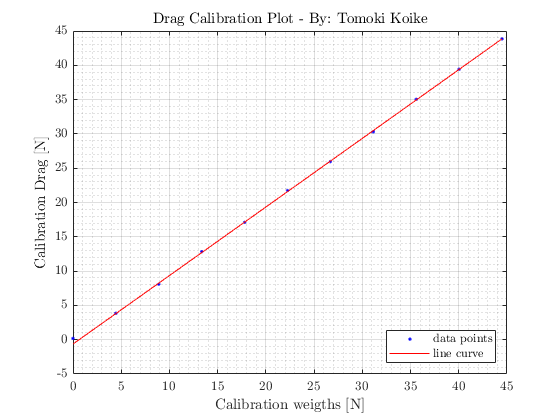

coeffs = coeffvalues(res_lift);  % Obtaining the coefficients
% Assigning the coefficients for the fitted curve 
c1_L = coeffs(1);
c2_L = coeffs(2);
c3_L = coeffs(3); 
% Defining a equation expression for lift scaling
syms lift
scale_lift = @(lift) -(c1_L*lift.^2 + c2_L*lift + c3_L);

% drag
[res_drag gof_drag] = createFit(calib_weights, calib_drags, 'Drag');

disp(res_drag);

     Linear model Poly2:
     res_drag(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =   5.698e-05  (-0.0006717, 0.0007856)
       p2 =      0.9975  (0.9638, 1.031)
       p3 =     -0.6245  (-0.9462, -0.3028)


coeffs = coeffvalues(res_drag);  % Obtaining the coefficients
% Assigning the coefficients for the fitted curve 
c1_D = coeffs(1);
c2_D = coeffs(2);
c3_D = coeffs(3); 
% Defining a equation expression for drag scaling
syms drag
scale_drag = @(drag) c1_D*drag.^2 + c2_D*drag + c3_D;

### <a>

Plot all the Cl vs AoA for all 5 different wings 

Since the Pitot tube reading gives the pressure difference we know that 


$$\Delta P_{\mathrm{pitot}} \;=\frac{1}{2}\rho v^2 \;\;$$


Thus,


$$C_L \;=\frac{L}{\frac{1}{2}\rho v^2 S}\;=\frac{L}{\Delta P_{\mathrm{pitot}} \;b\;c}\;$$


% Importing the data for all 5 different wings 
default = readmatrix("default.xlsx");
small_span = readmatrix("small_span.xlsx");
large_span = readmatrix("large_span.xlsx");
small_wingtip = readmatrix("small_wingtip.xlsx");
large_wingtip = readmatrix("large_wingtip.xlsx");

% Extract the pressure, temperature, velocity, lift, and wing span values  
% Default 
p_a1 = inchwater2pascal(default(:,1));  % [Pa]
T_a1 = default(:,2);  % [C]
v_a1 = default(:,3);  % [m/s]
L_a1 = lbs2newton(default(:,6));  % [N]
b1 = inch2m(12);  % [inch]
% Small span
p_a2 = inchwater2pascal(small_span(:,1));
T_a2 = small_span(:,2);
v_a2 = small_span(:,3);
L_a2 = lbs2newton(small_span(:,6));
b2 = inch2m(16);
% Large span
p_a3 = inchwater2pascal(large_span(:,1));
T_a3 = large_span(:,2);
v_a3 = large_span(:,3);
L_a3 = lbs2newton(large_span(:,6));
b3 = inch2m(32);
% Small wingtip
p_a4 = inchwater2pascal(small_wingtip(:,1));
T_a4 = small_wingtip(:,2);
v_a4 = small_wingtip(:,3);
L_a4 = lbs2newton(small_wingtip(:,6));
b4 = inch2m(16);
% Large wingtip
p_a5 = inchwater2pascal(large_wingtip(:,1));
T_a5 = large_wingtip(:,2);
v_a5 = large_wingtip(:,3);
L_a5 = lbs2newton(large_wingtip(:,6));
b5 = inch2m(15.5);

% Define angle of attack 
alpha = 0:2:24;

% Define chord length 
c = inch2m(8); 

% Computing the lift coefficients for all 5 different wings 
Cl_a1 = calc_lift_coeff(scale_lift(L_a1), p_a1, c, b1);
Cl_a2 = calc_lift_coeff(scale_lift(L_a2), p_a2, c, b2);
Cl_a3 = calc_lift_coeff(scale_lift(L_a3), p_a3, c, b3);
Cl_a4 = calc_lift_coeff(scale_lift(L_a4), p_a4, c, b4);
Cl_a5 = calc_lift_coeff(scale_lift(L_a5), p_a5, c, b5);

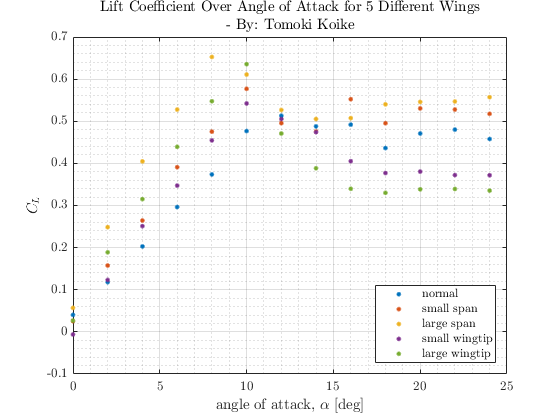

% Plotting 
fig1 = figure("Renderer","painters");
    plot(alpha, Cl_a1, '.', 'MarkerSize',10)
    xlabel('angle of attack, $\alpha$ [deg]')
    ylabel('$C_L$')
    title({'Lift Coefficient Over Angle of Attack for 5 Different Wings',['' ...
        '- By: Tomoki Koike']})
    hold on
    plot(alpha, Cl_a2, '.', 'MarkerSize', 10)
    plot(alpha, Cl_a3, '.', 'MarkerSize', 10)
    plot(alpha, Cl_a4, '.', 'MarkerSize', 10)
    plot(alpha, Cl_a5, '.', 'MarkerSize', 10)
    hold off
    legend('normal', 'small span', 'large span', 'small wingtip', 'large wingtip',...
        'Location','southeast')
    grid on
    grid minor 
    box on 
saveas(fig1, 'cl_vs_alpha_all.png');

### <b>

% For XFLR5 calculate Reynolds number with average values 
rho_avg1 = 2*mean(p_a1)./mean(v_a1.^2);
rho_avg2 = 2*mean(p_a2)./mean(v_a2.^2);
rho_avg3 = 2*mean(p_a3)./mean(v_a3.^2);
rho_avg4 = 2*mean(p_a4)./mean(v_a4.^2);
rho_avg5 = 2*mean(p_a5)./mean(v_a5.^2);
rho_avg = mean([rho_avg1,rho_avg2,rho_avg3,rho_avg4,rho_avg5])

rho_avg = 1.1702

v_avg = mean(mean([v_a1,v_a2,v_a3,v_a4,v_a5]))

v_avg = 12.1902

myu = 1.81*10^(-5);
Re_avg = rho_avg*v_avg*c/myu

Re_avg = 1.6015e+05

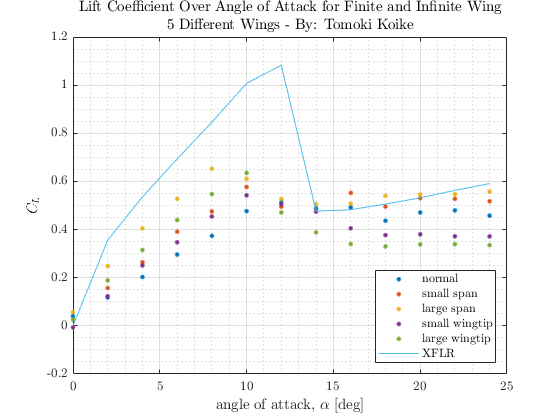


% Import XFLR results
xflr_res = readmatrix("Polar_Graph_3.csv");
xflr_alpha = xflr_res(:,1);
xflr_Cl = xflr_res(:,2);

% Plotting 
fig2 = figure("Renderer","painters");
    plot(alpha, Cl_a1, '.', 'MarkerSize',10)
    xlabel('angle of attack, $\alpha$ [deg]')
    ylabel('$C_L$')
    title({'Lift Coefficient Over Angle of Attack for Finite and Infinite Wing', ['' ...
        '5 Different Wings - By: Tomoki Koike']})
    hold on
    plot(alpha, Cl_a2, '.', 'MarkerSize', 10)
    plot(alpha, Cl_a3, '.', 'MarkerSize', 10)
    plot(alpha, Cl_a4, '.', 'MarkerSize', 10)
    plot(alpha, Cl_a5, '.', 'MarkerSize', 10)
    plot(xflr_alpha, xflr_Cl,'-')
    hold off
    legend('normal', 'small span', 'large span', 'small wingtip', 'large wingtip',...
        'XFLR','Location','southeast')
    grid on
    grid minor 
    box on 
saveas(fig2, 'cl_vs_alpha_inf_fin.png');

### <c>

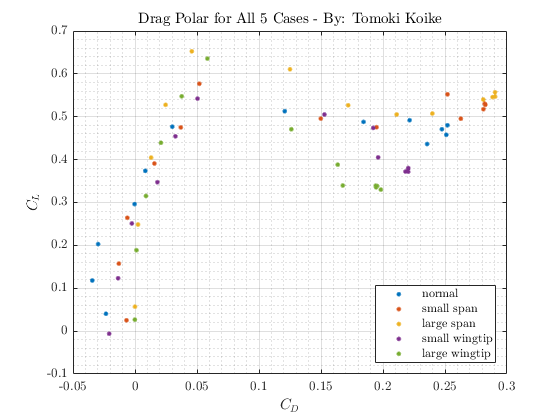

% Drags
D_a1 = lbs2newton(default(:,5));  % [N]
D_a2 = lbs2newton(small_span(:,5));
D_a3 = lbs2newton(large_span(:,5));
D_a4 = lbs2newton(small_wingtip(:,5));
D_a5 = lbs2newton(large_wingtip(:,5));

% Computing the drag coefficients for all 5 cases 
CD_a1 = calc_drag_coeff(scale_drag(D_a1), p_a1, c, b1);
CD_a2 = calc_drag_coeff(scale_drag(D_a2), p_a2, c, b2);
CD_a3 = calc_drag_coeff(scale_drag(D_a3), p_a3, c, b3);
CD_a4 = calc_drag_coeff(scale_drag(D_a4), p_a4, c, b4);
CD_a5 = calc_drag_coeff(scale_drag(D_a5), p_a5, c, b5);

% Plotting the drag polar for all 5 cases on one plot
fig3 = figure("Renderer","painters");
    plot(CD_a1, Cl_a1,'.', 'MarkerSize',10)
    title('Drag Polar for All 5 Cases - By: Tomoki Koike')
    xlabel('$C_D$')
    ylabel('$C_L$')
    hold on
    plot(CD_a2, Cl_a2,'.', 'MarkerSize',10)
    plot(CD_a3, Cl_a3,'.', 'MarkerSize',10)
    plot(CD_a4, Cl_a4,'.', 'MarkerSize',10)
    plot(CD_a5, Cl_a5,'.', 'MarkerSize',10)
    hold off
    legend('normal', 'small span', 'large span', 'small wingtip', 'large wingtip',...
        'Location','southeast')
    grid on 
    grid minor
    box on
saveas(fig3, 'drag_polar_all.png')

### <d>

Cl_a2_11 = interp1(alpha, Cl_a2, [11.0]);
Cl_a3_11 = interp1(alpha, Cl_a3, [11.0]);

CD_a2_11 = interp1(alpha, CD_a2, [11.0]);
CD_a3_11 = interp1(alpha, CD_a3, [11.0]);

L_D_a2 = Cl_a2./CD_a2;
[val1, idx1] = max(L_D_a2);
alpha1 = alpha(idx1);

L_D_a3 = Cl_a3./CD_a3;
[val2, idx2] = max(L_D_a3);
alpha2 = alpha(idx2);

### FUNCTIONS 

function N = lbs2newton(w)
    % Function that converts lbs to Newtons
    N = w*4.44822; 
end

function [fitresult, gof] = createFit(w, obj, obj_str)
    [xData, yData] = prepareCurveData( w, obj );
    
    % Set up fittype and options.
    ft = fittype( 'poly2' );
    opts = fitoptions( 'Method', 'LinearLeastSquares' );
    opts.Robust = 'Bisquare';
    
    % Fit model to data.
    [fitresult, gof] = fit( xData, yData, ft, opts );
    
    % Plot fit with data.
    fig = figure("Renderer","painters");
    plot( fitresult, xData, yData );
    % Label axes
    title(sprintf('%s Calibration Plot - By: Tomoki Koike',obj_str))
    xlabel('Calibration weigths [N]');
    ylabel(sprintf('Calibration %s [N]',obj_str));
    legend('data points', 'line curve', 'Location', 'southeast')
    grid on
    grid minor 
    box on
    saveas(fig, sprintf('%s_calib.png',obj_str))
end 

function P = inchwater2pascal(pf)
    P = pf * 248.82;
end

function Cl = calc_lift_coeff(L,p_diff,c,b)
    Cl = L./p_diff/c/b;
end 

function Cl = calc_drag_coeff(D,p_diff,c,b)
    Cl = D./p_diff/c/b;
end

function d = inch2m(l)
    d = l * 0.0254;
end